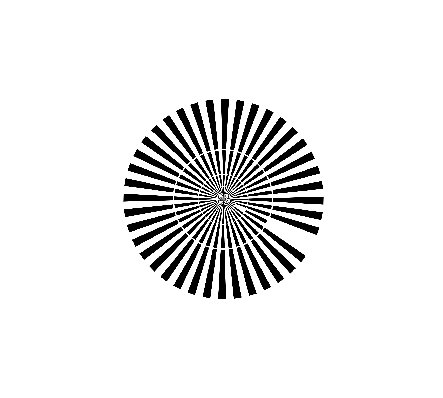

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

M = 10;

% Tamaño de la representación
Nx = 2048;
Ny = Nx;

% Condiciones de muestreo
seleccionador = 2; 

if seleccionador == 1
    dx = 6.513*mm/(Nx*M);
elseif seleccionador == 2
    dx = 60*nm;
end

dy = dx;

% Longitud de Onda de emisión

lambda = 720*nm;


% Apertura númerica
AN = 0.25;

estrella = imread('SiemensStar_2048_AD.png');
estrella2 = imresize(estrella,4096/2048);
%estrella = imresize(estrella,Nx/780);
estrella = rgb2gray(estrella);
imshow(estrella)
colormap("gray")

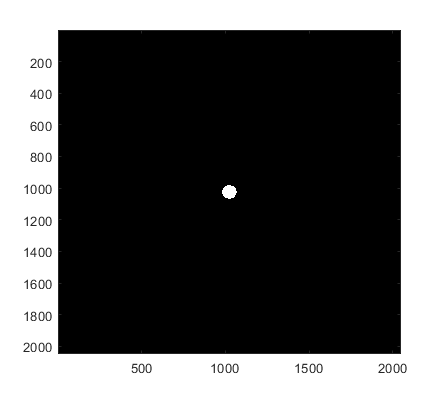


%La imagen pasará por un primer lente, el cual es un 
% objetivo 10x, en su distancia focal, lo cual representa 
% una transformada de Fourier.

f2 = 200*mm;


%Microscopio de un foton 

[salidaPura, observacion, pupila] = microscopio(estrella,M,f2,AN, Nx, Ny, dx, dy, lambda);
observacion = imrotate(observacion,180);
imagesc(pupila)
colormap("gray")

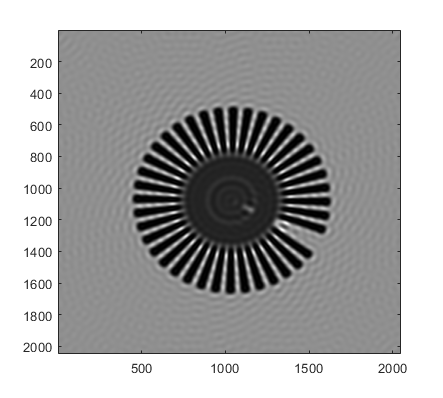

imagesc(observacion)
colormap("gray")


%Microscopio de dos fotones 